data=table2array(readtable('fashion-mnist_train.csv'));


numclasses = 10;
numsamples = 30000;
labels = data(1:numsamples,1);
X=data(1:numsamples,2:end);

coeff = pca(X);
coeff = coeff(:,1:100);
pca_data = X * coeff;
W = weights(pca_data,numsamples);

ctr = 1;
accuracy = zeros(11,20);
labels = labels';

tic
for numlabeled = [10,20,30,40,50,100,500,1000,5000]
    for k = 1:20
        firstlabs = [];
        for i = 0:9
            idx = find(labels==i);
            perm = randperm(length(idx),numlabeled/10);
            firstlabs = [firstlabs idx(perm)];
        end
        
        B = zeros(10,numsamples);
        yhat = 0.1*ones(10,1);

        for j = 1:length(firstlabs)
            labvec = zeros(10,1);
            labvec(labels(firstlabs(j))+1) = 1;
            labvec = labvec - yhat;
            B(:,firstlabs(j)) = labvec;
        end
        sum(sum(B))
        %Y = labels(1:numlabeled);
        %F = onehotencode(Y,1,'ClassNames',0:1:9);
        b = 0.1*ones(10,1);
        %p = zeros(numims,1);
        %p(firstlabs) = 1;
        %pinf = W*ones(numims,1)/(ones(1,numims)*W*ones(numims,1));
        vec = sum(W,2);
        n = length(vec);
        D = spdiags(vec,0,n,n);
        L = D-W;
        %yhat = (1/numlabeled)*F*ones(numlabeled,1);
        %B = [F-yhat zeros(10,numims - numlabeled)];
        U = zeros(numsamples,10);
        for t = 1:100
            U = U+D\(B'-L*U);
            %p = W*inv(D)*p;
            %max(p - pinf);
        end
        U = U*diag(b./yhat);
        [~,predclass] = max(U');
        predclass = predclass-1;
        predclasses = predclass(setdiff(1:end,firstlabs));
        truelabels = labels(setdiff(1:end,firstlabs));
        accuracy(ctr,k) = sum(predclasses==truelabels)/length(truelabels);
    end
    ctr = ctr+1;
end

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 6.6613e-16

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.3323e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 1.9984e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 2.6645e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 3.3307e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 6.6613e-15

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 3.3307e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 6.6613e-14

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

ans = 3.3307e-13

toc

Elapsed time is 92.298811 seconds.


save('fmW1.mat','accuracy')

fashionmnistresult = 1-mean(accuracy,2)

fashionmnistresult =     0.4173
    0.3636
    0.3315
    0.3151
    0.3018
    0.2711
    0.2295
    0.2203
    0.2159
    1.0000


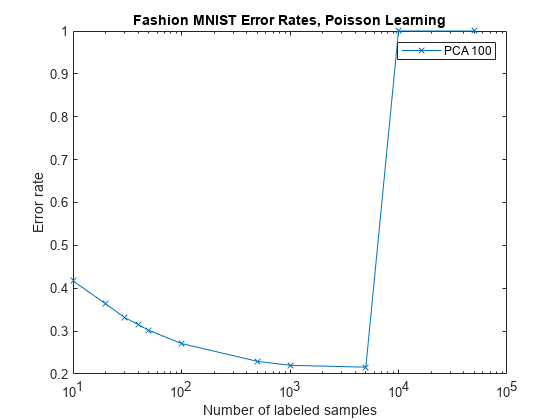

x = [10,20,30,40,50,100,500,1000,5000,10000,50000];

semilogx(x,fashionmnistresult,'-x')
title('Fashion MNIST Error Rates, Poisson Learning')
xlabel('Number of labeled samples')
ylabel('Error rate')
legend('PCA 100')

print(gcf,'-dpng','FashionMNISTResults.png')

function W = weights(data,numims)
    W = spalloc(numims,numims,1000000);
    Idx = knnsearch(data,data,'K',11);
    for i = 1:numims
        dkxi = norm(data(Idx(i,11),:) - data(i,:));
        for j = 1:10
            %W(i,Idx(i,j+1))=exp(-4*(norm(data(Idx(i,j+1),:) - data(i,:)))^2/dkxi^2);
            W(i,Idx(i,j+1)) = 1;
        end
        W(i,:) = W(i,:)/sum(W(i,:));
    end
    W = W + W';
end